clear all
syms x(t) y(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

The unknown functions (just the base functions, not derivatives) are: Ff(t),N(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Ff: 1.721276 Fft:0.000000
N: 9.232456 Nt:0.000000
theta: 0.523599 thetat:0.000000
x: 0.000000 xt:0.000000
y: 1.000000 yt:0.000000
Dthetat: 0.000000 Dthetatt:-27.216117
Dxt: 0.000000 Dxtt:1.721276
Dyt: 0.000000 Dytt:-0.577544


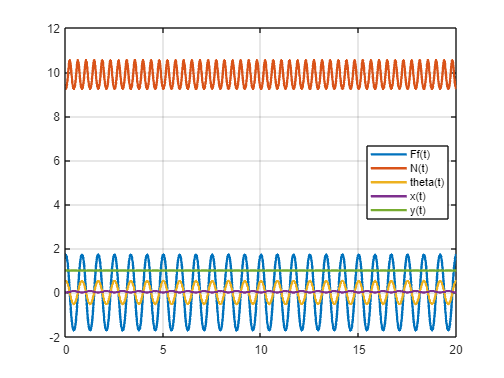

%Solve using the numerical solver.  The "unknown functions" are still x, y,
%theta, and the DE is second order in all of them.  So, you'll need to
%provide an initial condition for x and y.  Or whatever.  In any case,
%you'll need three state variables.  Essentially, you have said that we
%have to roll along the ground, but we have not said where the ground is. 

theta0 = pi/6;
omega0 = 0;
x0=0; y0=1;


soln=mechanicsAsDAE(DES,disp_const,vel_const,[0,20],{theta==theta0,diff(theta)==omega0,x==x0,y==y0});